%% LOAD COSMIC-2 DATA
disp('Loading COSMIC-2 data...')

Loading COSMIC-2 data...



n_profiles = numel(COSMIC_data);

c2_nmf2     = NaN(n_profiles, 1);
c2_lat      = NaN(n_profiles, 1);
c2_lon      = NaN(n_profiles, 1);
c2_hmf2     = NaN(n_profiles, 1);
c2_hour     = NaN(n_profiles, 1);

for i = 1:n_profiles
    profile = COSMIC_data{i};

    c2_nmf2(i) = profile.edmax;    
    c2_lat(i)  = profile.edmaxlat;   
    c2_lon(i)  = profile.edmaxlon;  
    c2_hmf2(i) = profile.edmaxalt; 
    c2_hour(i) = profile.hour;  
end

%APPLY TIME MASK AND REMOVE FILL VALUES
c2_nmf2(c2_nmf2 < 0) = NaN;

time_mask = (c2_hour >= 22.0) & (c2_hour <= 24.0);
valid     = ~isnan(c2_nmf2) & time_mask;

c2_nmf2 = c2_nmf2(valid);
c2_hmf2 = c2_hmf2(valid);
c2_lat  = c2_lat(valid);
c2_lon  = c2_lon(valid);
c2_hour = c2_hour(valid);

fprintf('COSMIC-2 profiles in 22:00–24:00 UTC: %d / %d\n', sum(valid), n_profiles)

COSMIC-2 profiles in 22:00–24:00 UTC: 252 / 2551



%INTERPOLATE IRI NmF2 TO COSMIC-2 LOCATIONS
iri_nmf2_interp = griddata(peak_lon, peak_lat, peak_ne, c2_lon, c2_lat, 'linear');

outside = isnan(iri_nmf2_interp);
fprintf('COSMIC-2 points outside IRI grid: %d\n', sum(outside))

COSMIC-2 points outside IRI grid: 14



c2_nmf2_cmp  = c2_nmf2(~outside);
iri_nmf2_cmp = iri_nmf2_interp(~outside);
cmp_lat      = c2_lat(~outside);
cmp_lon      = c2_lon(~outside);

%COMPUTE DIFFERENCE
diff_ne = c2_nmf2_cmp - iri_nmf2_cmp;

bias     = mean(diff_ne, 'omitnan');
rmse     = sqrt(mean(diff_ne.^2, 'omitnan'));
corr_mat = corrcoef(c2_nmf2_cmp, iri_nmf2_cmp);
r        = corr_mat(1,2);

fprintf('\n── Comparison statistics (22:00–24:00 UTC) ─────────\n')


── Comparison statistics (22:00–24:00 UTC) ─────────


fprintf('N points:           %d\n',         numel(diff_ne))

N points:           238


fprintf('Bias (C2 - IRI):    %.3e cm⁻³\n', bias)

Bias (C2 - IRI):    -7.281e+04 cm⁻³


fprintf('RMSE:               %.3e cm⁻³\n', rmse)

RMSE:               4.744e+05 cm⁻³


fprintf('Pearson r:          %.3f\n',       r)

Pearson r:          0.855


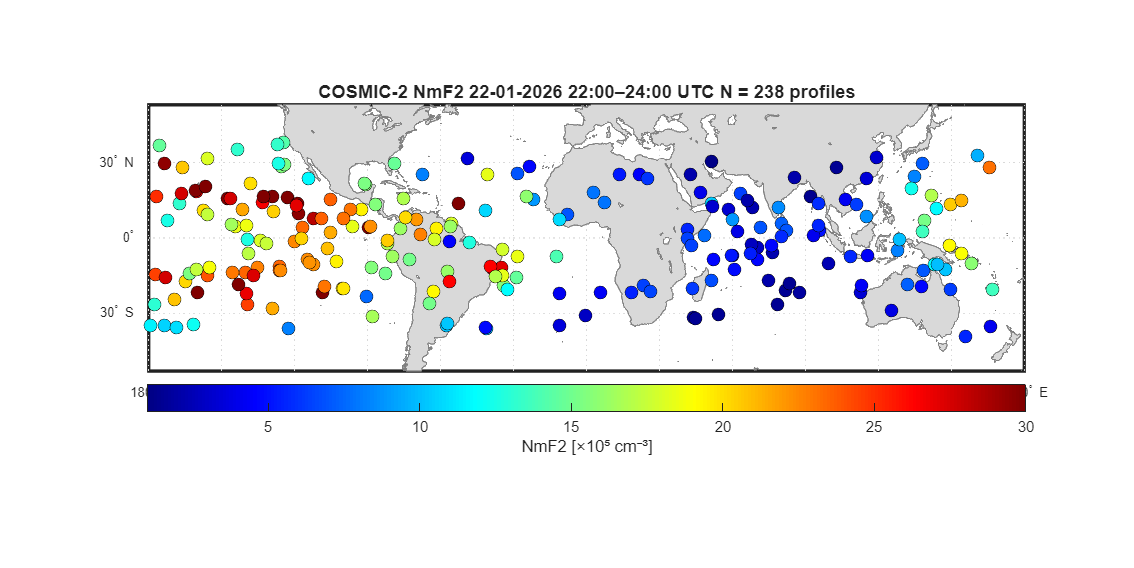


%MAP OF COSMIC-2 NmF2 MEASUREMENTS
c2_scaled = c2_nmf2_cmp / 1e5;    
vmin_c2   = 1;
vmax_c2   = 30;

cmap_c2       = jet(256);
c2_clamped    = max(vmin_c2, min(vmax_c2, c2_scaled));
ci_c2         = round((c2_clamped - vmin_c2) / (vmax_c2 - vmin_c2) * 255) + 1;
colors_c2     = cmap_c2(ci_c2, :);

fig2 = figure('Name', 'COSMIC-2 NmF2 Map', 'NumberTitle','off', ...
              'Color','white', 'Position',[100 100 1200 600]);

ax2 = worldmap([-50 50], [-180 180]);
setm(ax2, 'MeridianLabel','on', 'ParallelLabel','on', ...
          'MLabelParallel','south', 'FontSize', 8);
geoshow(ax2, land, 'FaceColor',[0.85 0.85 0.85], 'EdgeColor',[0.5 0.5 0.5]);


scatterm(ax2, cmp_lat, cmp_lon, 60, colors_c2, 'filled', ...
         'MarkerEdgeColor','k', 'LineWidth', 0.3);

cb2 = colorbar(ax2, 'southoutside');
colormap(ax2, cmap_c2);
clim([vmin_c2 vmax_c2]);
cb2.Label.String = 'NmF2 [×10⁵ cm⁻³]';
cb2.Label.FontSize = 10;

title(ax2, sprintf('COSMIC-2 NmF2 22-01-2026 22:00–24:00 UTC N = %d profiles', ...
      numel(c2_nmf2_cmp)), 'FontSize', 11);


gridm('on');
fprintf('COSMIC-2 map saved as cosmic2_nmf2_map.png\n')

COSMIC-2 map saved as cosmic2_nmf2_map.png


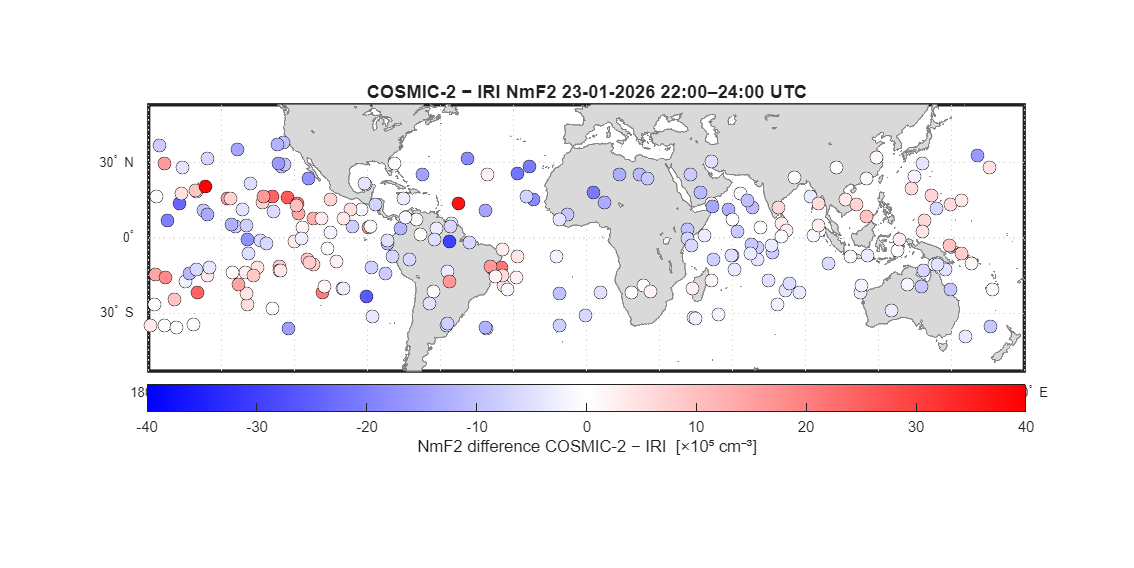

%MAP OF COSMIC-2 MINUS IRI
diff_ne = c2_nmf2_cmp - iri_nmf2_cmp;   


diff_scaled = diff_ne / 1e5;         
clim_max    = max(abs(diff_scaled), [], 'omitnan');  
clim_max    = ceil(clim_max);     


n = 256;
r = [linspace(0,1,n/2), ones(1,n/2)];
g = [linspace(0,1,n/2), linspace(1,0,n/2)];
b = [ones(1,n/2),       linspace(1,0,n/2)];
cmap_div = [r', g', b'];         

diff_clamped = max(-clim_max, min(clim_max, diff_scaled));
ci_div       = round((diff_clamped + clim_max) / (2*clim_max) * 255) + 1;
ci_div       = max(1, min(256, ci_div));
colors_div   = cmap_div(ci_div, :);

fig3 = figure('Name', 'COSMIC-2 minus IRI', 'NumberTitle','off', ...
              'Color','white', 'Position',[100 100 1200 600]);

ax3 = worldmap([-50 50], [-180 180]);
setm(ax3, 'MeridianLabel','on', 'ParallelLabel','on', ...
          'MLabelParallel','south', 'FontSize', 8);
geoshow(ax3, land, 'FaceColor',[0.85 0.85 0.85], 'EdgeColor',[0.5 0.5 0.5]);

scatterm(ax3, cmp_lat, cmp_lon, 60, colors_div, 'filled', ...
         'MarkerEdgeColor','k', 'LineWidth', 0.3);

cb3 = colorbar(ax3, 'southoutside');
colormap(ax3, cmap_div);
clim([-40 40]);
cb3.Label.String = 'NmF2 difference COSMIC-2 − IRI  [×10⁵ cm⁻³]';
cb3.Label.FontSize = 10;

title(ax3, sprintf('COSMIC-2 − IRI NmF2 %02d-01-2026 22:00–24:00 UTC', ...
    day), 'FontSize', 11);

gridm('on');
exportgraphics(fig3, sprintf('%02d0126 cosmic2_minus_iri_map_V2.png',day), 'Resolution', 300);

fprintf('Difference map saved as cosmic2_minus_iri_map.png\n')

Difference map saved as cosmic2_minus_iri_map.png


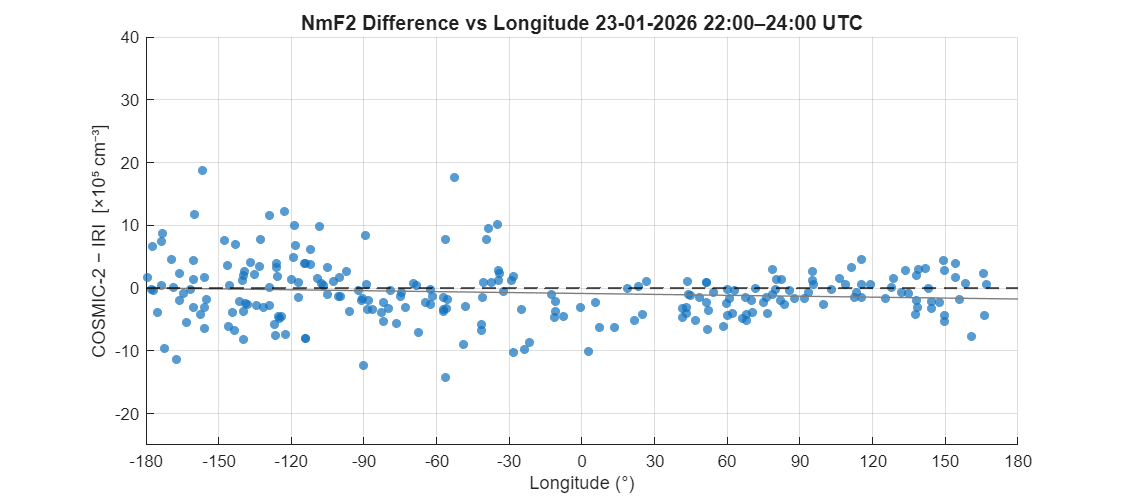



figure('Color','white', 'Position',[100 100 900 400])

scatter(cmp_lon, diff_ne/1e5, 30, 'filled', ...
        'MarkerEdgeColor','none', 'MarkerFaceAlpha', 0.7)
lsline

yline(0,  'k--', 'LineWidth', 1.2)                   

xlabel('Longitude (°)',                       'FontSize', 11)
ylabel('COSMIC-2 − IRI  [×10⁵ cm⁻³]',       'FontSize', 11)
title(sprintf('NmF2 Difference vs Longitude %02d-01-2026 22:00–24:00 UTC', day), 'FontSize', 12)
grid on
xlim([-180 180])
ylim([-25 40])
xticks(-180:30:180)

exportgraphics(gcf, sprintf('%02d0126 diff_vs_longitude_V2.png', day), 'Resolution', 300)

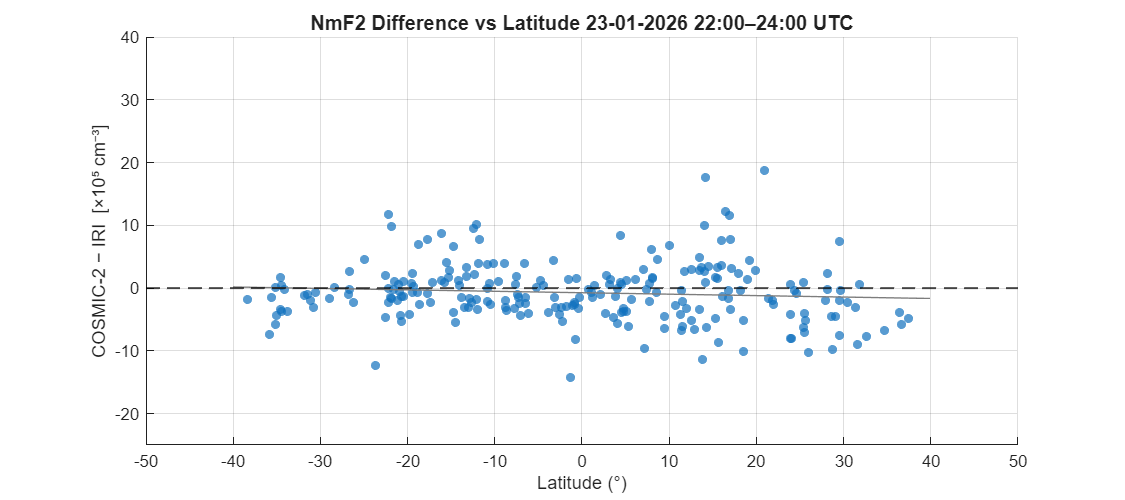

%DIFFERENCE VS LATITUDE 
figure('Color','white', 'Position',[100 100 900 400])

scatter(cmp_lat, diff_ne/1e5, 30, 'filled', ...
        'MarkerEdgeColor','none', 'MarkerFaceAlpha', 0.7)
lsline
clim([-180 180])

yline(0, 'k--', 'LineWidth', 1.2)

xlabel('Latitude (°)',                        'FontSize', 11)
ylabel('COSMIC-2 − IRI  [×10⁵ cm⁻³]',       'FontSize', 11)
title(sprintf('NmF2 Difference vs Latitude %02d-01-2026 22:00–24:00 UTC', day), 'FontSize', 12)
grid on
xlim([-50 50])
ylim([-25 40])
xticks(-50:10:50)

exportgraphics(gcf, sprintf('%02d0126 diff_vs_latitude_V2.png',day), 'Resolution', 300)

%BIAS AND RMSE BY HEMISPHERE AND LONGITUDE BAND


hemispheres = {'Northern', 'Southern'};
hem_masks   = {cmp_lat >= 0, cmp_lat < 0};

fprintf('\n── Hemisphere Statistics ───────────────────────────────────────\n')


── Hemisphere Statistics ───────────────────────────────────────


fprintf('%-25s  %6s  %10s  %10s\n', 'Region', 'N', 'Bias', 'RMSE')

Region                          N        Bias        RMSE


fprintf('%s\n', repmat('-',1,60))

------------------------------------------------------------



hem_bias = NaN(2,1);
hem_rmse = NaN(2,1);
hem_n    = NaN(2,1);

for i = 1:2
    d = diff_ne(hem_masks{i});
    if isempty(d), continue; end
    hem_bias(i) = mean(d, 'omitnan');
    hem_rmse(i) = sqrt(mean(d.^2, 'omitnan'));
    hem_n(i)    = sum(~isnan(d));
    fprintf('%-25s  %6d  %10.3e  %10.3e  cm⁻³\n', ...
            hemispheres{i}, hem_n(i), hem_bias(i), hem_rmse(i))
end

Northern                      116  -9.411e+04   5.419e+05  cm⁻³
Southern                      122  -5.255e+04   3.998e+05  cm⁻³



%90° LONGITUDE BANDS 
lon_edges_90 = -180:90:180;     
n_bands_90   = numel(lon_edges_90) - 1; 
band_bias_90 = NaN(n_bands_90, 1);
band_rmse_90 = NaN(n_bands_90, 1);
band_n_90    = NaN(n_bands_90, 1);
band_label_90 = cell(n_bands_90, 1);

fprintf('\n── 90° Longitude Band Statistics ───────────────────────────────\n')


── 90° Longitude Band Statistics ───────────────────────────────


fprintf('%-20s %6s %10s %10s\n', 'Band', 'N', 'Bias', 'RMSE')

Band                      N       Bias       RMSE


fprintf('%s\n', repmat('-',1,55))

-------------------------------------------------------



for i = 1:n_bands_90
    lo = lon_edges_90(i);
    hi = lon_edges_90(i+1);

    if i < n_bands_90
        mask = (cmp_lon >= lo) & (cmp_lon < hi);
    else
        mask = (cmp_lon >= lo) & (cmp_lon <= hi);
    end

    band_label_90{i} = sprintf('%d° to %d°', lo, hi);
    d = diff_ne(mask);

    if isempty(d) || all(isnan(d))
        fprintf('%-20s %6d %10s %10s\n', band_label_90{i}, 0, 'N/A', 'N/A')
        continue
    end

    band_bias_90(i) = mean(d, 'omitnan');
    band_rmse_90(i) = sqrt(mean(d.^2, 'omitnan'));
    band_n_90(i)    = sum(~isnan(d));

    fprintf('%-20s %6d %10.3e %10.3e cm⁻³\n', ...
        band_label_90{i}, band_n_90(i), band_bias_90(i), band_rmse_90(i))
end

-180° to -90°            89  3.842e+04  5.538e+05 cm⁻³
-90° to 0°               55 -1.460e+05  5.539e+05 cm⁻³
0° to 90°                50 -2.374e+05  3.499e+05 cm⁻³
90° to 180°              44 -1.935e+04  2.723e+05 cm⁻³



%30° LONGITUDE BANDS
lon_edges  = -180:30:180;                   
n_bands    = numel(lon_edges) - 1;     
band_bias  = NaN(n_bands, 1);
band_rmse  = NaN(n_bands, 1);
band_n     = NaN(n_bands, 1);
band_label = cell(n_bands, 1);

fprintf('\n── 30° Longitude Band Statistics ───────────────────────────────\n')


── 30° Longitude Band Statistics ───────────────────────────────


fprintf('%-20s  %6s  %10s  %10s\n', 'Band', 'N', 'Bias', 'RMSE')

Band                       N        Bias        RMSE


fprintf('%s\n', repmat('-',1,55))

-------------------------------------------------------



for i = 1:n_bands
    lo = lon_edges(i);
    hi = lon_edges(i+1);


    if i < n_bands
        mask = (cmp_lon >= lo) & (cmp_lon < hi);
    else
        mask = (cmp_lon >= lo) & (cmp_lon <= hi);
    end

    band_label{i} = sprintf('%d° to %d°', lo, hi);
    d = diff_ne(mask);

    if isempty(d) || all(isnan(d))
        fprintf('%-20s  %6d  %10s  %10s\n', band_label{i}, 0, 'N/A', 'N/A')
        continue
    end

    band_bias(i) = mean(d, 'omitnan');
    band_rmse(i) = sqrt(mean(d.^2, 'omitnan'));
    band_n(i)    = sum(~isnan(d));

    fprintf('%-20s  %6d  %10.3e  %10.3e  cm⁻³\n', ...
            band_label{i}, band_n(i), band_bias(i), band_rmse(i))
end

-180° to -150°            27   6.291e+04   6.304e+05  cm⁻³
-150° to -120°            34  -1.295e+04   5.339e+05  cm⁻³
-120° to -90°             28   7.719e+04   4.956e+05  cm⁻³
-90° to -60°              21  -1.828e+05   3.552e+05  cm⁻³
-60° to -30°              22   2.973e+04   6.924e+05  cm⁻³
-30° to 0°                12  -4.036e+05   5.536e+05  cm⁻³
0° to 30°                  9  -3.693e+05   5.090e+05  cm⁻³
30° to 60°                18  -2.405e+05   3.336e+05  cm⁻³
60° to 90°                23  -1.833e+05   2.788e+05  cm⁻³
90° to 120°               16   4.165e+04   1.913e+05  cm⁻³
120° to 150°              20  -5.228e+04   2.851e+05  cm⁻³
150° to 180°               8  -5.899e+04   3.626e+05  cm⁻³


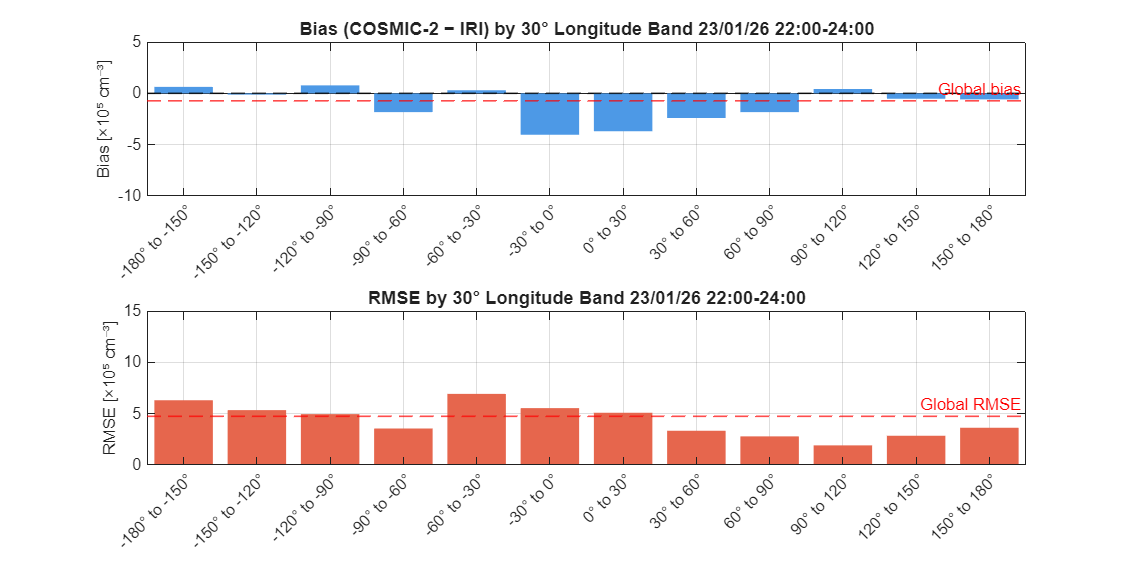


%PLOT BIAS AND RMSE BY LONGITUDE BAND
band_centres = lon_edges(1:end-1) + 15;  
figure('Color','white', 'Position',[100 100 1000 500])
subplot(2,1,1)
ax_bias = gca; 
bar(band_centres, band_bias/1e5, 'FaceColor',[0.3 0.6 0.9], 'EdgeColor','none')
hold on
yline(0, 'k--', 'LineWidth', 1)
yline(mean(diff_ne,'omitnan')/1e5, 'r--', 'LineWidth', 1, 'Label', 'Global bias')
xticks(band_centres)
xticklabels(band_label)
xtickangle(45)
ylabel('Bias [×10⁵ cm⁻³]', 'FontSize', 10)
title(sprintf('Bias (COSMIC-2 − IRI) by 30° Longitude Band %02d/01/26 22:00-24:00', day), 'FontSize', 11)
grid on
xlim([-180 180])
ylim(ax_bias, [-10 5]) 


subplot(2,1,2)
bar(band_centres, band_rmse/1e5, 'FaceColor',[0.9 0.4 0.3], 'EdgeColor','none')
hold on
yline(rmse/1e5, 'r--', 'LineWidth', 1, ...
      'Label', 'Global RMSE')
xticks(band_centres)
xticklabels(band_label)
xtickangle(45)
ylabel('RMSE [×10⁵ cm⁻³]', 'FontSize', 10)
title(sprintf('RMSE by 30° Longitude Band %02d/01/26 22:00-24:00', day), 'FontSize', 11)
grid on
xlim([-180 180])
ylim([0 15])

exportgraphics(gcf, sprintf('%02d0126 bias_rmse_lon_bands_V2.png',day), 'Resolution', 300)

fprintf('\nLongitude band plot saved.\n')


Longitude band plot saved.


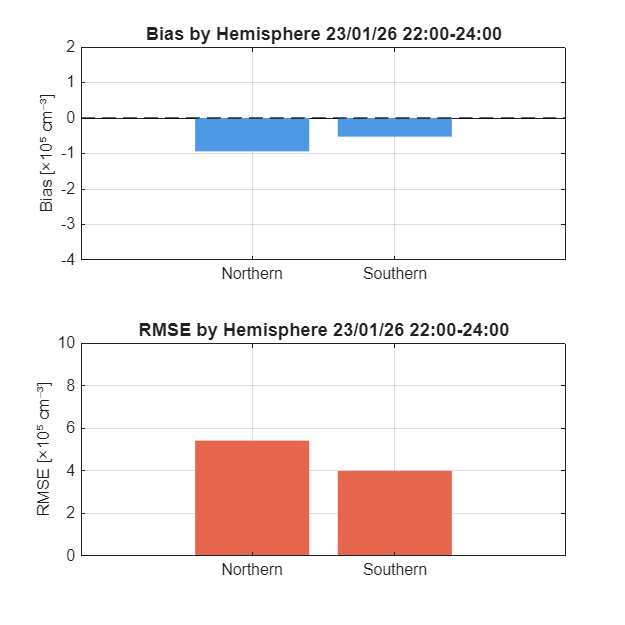


%PLOT BIAS AND RMSE BY HEMISPHERE
figure('Color','white', 'Position',[100 100 500 500])

subplot(2,1,1)
bar(1:2, hem_bias/1e5, 'FaceColor',[0.3 0.6 0.9], 'EdgeColor','none')
hold on
yline(0, 'k--', 'LineWidth', 1)
xticks(1:2)
xticklabels(hemispheres)
ylabel('Bias [×10⁵ cm⁻³]', 'FontSize', 10)
title(sprintf('Bias by Hemisphere %02d/01/26 22:00-24:00', day), 'FontSize', 11)
ylim([-4 2])
grid on

subplot(2,1,2)
bar(1:2, hem_rmse/1e5, 'FaceColor',[0.9 0.4 0.3], 'EdgeColor','none')
hold on
xticks(1:2)
xticklabels(hemispheres)
ylabel('RMSE [×10⁵ cm⁻³]', 'FontSize', 10)
title(sprintf('RMSE by Hemisphere %02d/01/26 22:00-24:00', day), 'FontSize', 11)
ylim([0 10])
grid on

exportgraphics(gcf, sprintf('%02d0126 bias_rmse_hemispheres_V2.png',day), 'Resolution', 300)

fprintf('Hemisphere plot saved.\n')

Hemisphere plot saved.


%SUMMARY STATISTICS TABLE
clear mean max  

fprintf('\n════════════════════════════════════════════════════════════════\n')


════════════════════════════════════════════════════════════════


fprintf('  SUMMARY STATISTICS — 22-01-2026 | 22:00–24:00 UTC\n')

  SUMMARY STATISTICS — 22-01-2026 | 22:00–24:00 UTC


fprintf('════════════════════════════════════════════════════════════════\n')

════════════════════════════════════════════════════════════════


fprintf('%-30s  %12s\n', 'Metric', 'Value')

Metric                                 Value


fprintf('%s\n', repmat('-',1,50))

--------------------------------------------------



%Global
valid_ne         = c2_nmf2_cmp(~isnan(c2_nmf2_cmp));
valid_diff       = diff_ne(~isnan(diff_ne));

global_peak_nmf2 = max(valid_ne);
global_avg_nmf2  = sum(valid_ne)  / numel(valid_ne);
global_bias      = sum(valid_diff) / numel(valid_diff);
global_rmse      = sqrt(sum(valid_diff.^2) / numel(valid_diff));

fprintf('%-30s  %12.3e cm^-3\n', 'Peak NmF2',     global_peak_nmf2)

Peak NmF2                          4.359e+06 cm^-3


fprintf('%-30s  %12.3e cm^-3\n', 'Average NmF2',  global_avg_nmf2)

Average NmF2                       1.410e+06 cm^-3


fprintf('%-30s  %12.3e cm^-3\n', 'Global Bias',   global_bias)

Global Bias                       -7.281e+04 cm^-3


fprintf('%-30s  %12.3e cm^-3\n', 'Global RMSE',   global_rmse)

Global RMSE                        4.744e+05 cm^-3


fprintf('%s\n', repmat('-',1,50))

--------------------------------------------------



%Hemisphere loop
hem_labels = {'Northern', 'Southern'};
hem_masks  = {cmp_lat >= 0, cmp_lat < 0};

for i = 1:2
    m  = hem_masks{i};
    d  = diff_ne(m);
    ne = c2_nmf2_cmp(m);
    ne = ne(~isnan(ne));
    d  = d(~isnan(d));

    if isempty(ne) || isempty(d)
        lbl = hem_labels{i};
        fprintf('%-30s  %12s\n', [lbl ' Bias'],    'N/A')
        fprintf('%-30s  %12s\n', [lbl ' RMSE'],    'N/A')
        fprintf('%-30s  %12s\n', [lbl ' Peak'],    'N/A')
        fprintf('%-30s  %12s\n', [lbl ' Average'], 'N/A')
        fprintf('%s\n', repmat('-',1,50))
        continue
    end

    h_peak = max(ne);
    h_avg  = sum(ne) / numel(ne);
    h_bias = sum(d)  / numel(d);
    h_rmse = sqrt(sum(d.^2) / numel(d));

    lbl = hem_labels{i};
    fprintf('%-30s  %12.3e cm^-3\n', [lbl ' Bias'],    h_bias)
    fprintf('%-30s  %12.3e cm^-3\n', [lbl ' RMSE'],    h_rmse)
    fprintf('%-30s  %12.3e cm^-3\n', [lbl ' Peak'],    h_peak)
    fprintf('%-30s  %12.3e cm^-3\n', [lbl ' Average'], h_avg)
    fprintf('%s\n', repmat('-',1,50))
end

Northern Bias                     -9.411e+04 cm^-3


Northern RMSE                      5.419e+05 cm^-3


Northern Peak                      4.359e+06 cm^-3


Northern Average                   1.496e+06 cm^-3


--------------------------------------------------


Southern Bias                     -5.255e+04 cm^-3


Southern RMSE                      3.998e+05 cm^-3


Southern Peak                      3.292e+06 cm^-3


Southern Average                   1.329e+06 cm^-3


--------------------------------------------------



% 90° Longitude bands
lon_edges_90 = [-180, -90, 0, 90, 180];
n_bands_90   = numel(lon_edges_90) - 1;

for i = 1:n_bands_90
    lo = lon_edges_90(i);
    hi = lon_edges_90(i+1);

    if i < n_bands_90
        m = (cmp_lon >= lo) & (cmp_lon < hi);
    else
        m = (cmp_lon >= lo) & (cmp_lon <= hi);
    end

    d  = diff_ne(m);
    ne = c2_nmf2_cmp(m);

    ne = ne(~isnan(ne));
    d  = d(~isnan(d));

    lbl = sprintf('%d to %d', lo, hi);

    if isempty(ne) || isempty(d)
        fprintf('%-30s  %12s\n', [lbl ' Bias'],    'N/A')
        fprintf('%-30s  %12s\n', [lbl ' RMSE'],    'N/A')
        fprintf('%-30s  %12s\n', [lbl ' Peak'],    'N/A')
        fprintf('%-30s  %12s\n', [lbl ' Average'], 'N/A')
        fprintf('%s\n', repmat('-',1,50))
        continue
    end

    b_peak = max(ne);
    b_avg  = sum(ne) / numel(ne);
    b_bias = sum(d)  / numel(d);
    b_rmse = sqrt(sum(d.^2) / numel(d));

    fprintf('%-30s  %12.3e cm^-3\n', [lbl ' Bias'],    b_bias)
    fprintf('%-30s  %12.3e cm^-3\n', [lbl ' RMSE'],    b_rmse)
    fprintf('%-30s  %12.3e cm^-3\n', [lbl ' Peak'],    b_peak)
    fprintf('%-30s  %12.3e cm^-3\n', [lbl ' Average'], b_avg)
    fprintf('%s\n', repmat('-',1,50))
end

-180 to -90 Bias                   3.842e+04 cm^-3


-180 to -90 RMSE                   5.538e+05 cm^-3


-180 to -90 Peak                   4.359e+06 cm^-3


-180 to -90 Average                2.121e+06 cm^-3


--------------------------------------------------


-90 to 0 Bias                     -1.460e+05 cm^-3


-90 to 0 RMSE                      5.539e+05 cm^-3


-90 to 0 Peak                      3.883e+06 cm^-3


-90 to 0 Average                   1.544e+06 cm^-3


--------------------------------------------------


0 to 90 Bias                      -2.374e+05 cm^-3


0 to 90 RMSE                       3.499e+05 cm^-3


0 to 90 Peak                       1.037e+06 cm^-3


0 to 90 Average                    4.599e+05 cm^-3


--------------------------------------------------


90 to 180 Bias                    -1.935e+04 cm^-3


90 to 180 RMSE                     2.723e+05 cm^-3


90 to 180 Peak                     2.315e+06 cm^-3


90 to 180 Average                  8.859e+05 cm^-3


--------------------------------------------------



fprintf('════════════════════════════════════════════════════════════════\n')

════════════════════════════════════════════════════════════════
